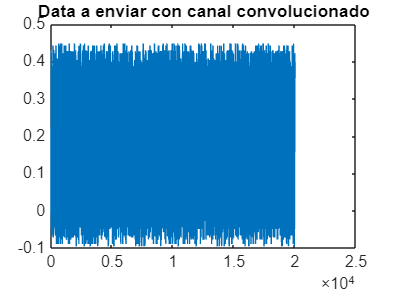

%% OOK System with Pilot-based LS Channel Estimation and Equalization
clear; clc; close all;

run("main_channel.m")


% -----------------------
% Simulation Parameters
% -----------------------
numDataBits   = 10e3;     % Number of data bits
numPilotBits  = 100;      % Number of pilot bits
SNRdB         = 20;       % SNR in dB
threshold     = 0.5;      % Decision threshold for OOK after equalization
sps           = 8;        % Samples per symbol (oversampling factor)
rolloff       = 0.35;     % RRC rolloff factor
span          = 6;        % Filter span in symbols for RRC
rng('default');           % Reproducibility

% -----------------------
% Generate Data & Pilot
% -----------------------
dataBits  = randi([0 1], numDataBits, 1);
pilotBits = randi([0 1], numPilotBits, 1);

% Concatenate pilot + data for transmission
txBits = [pilotBits; dataBits];
numTotalBits = length(txBits);

% -----------------------
% OOK Mapping
% -----------------------
% Map bits 0->0, 1->1
txSymbols = double(txBits);   % still at "symbol rate" (1 sample per symbol)

% -----------------------
% RRC Filter Design
% -----------------------
% Create a square-root raised cosine filter for pulse shaping (and matched filtering).
% rcosdesign(rolloff, span, sps, shape='sqrt')
rrcFilter = rcosdesign(rolloff, span, sps, 'sqrt');  

% -----------------------
% Transmit Pulse Shaping
% -----------------------
% 1) Upsample symbols by 'sps'
% 2) Convolve with the RRC filter
txUpsampled = upsample(txSymbols, sps);
txPulseShaped = conv(txUpsampled, rrcFilter, 'same');  
% 'same' keeps output length = length(txUpsampled)

%% 3. Channel Model
% Single-tap channel with some amplitude and phase
% Adjust as needed to simulate multi-path or more complex channels
h = Final_response;  % Example complex channel gain

% Pass the OOK signal through the channel
rxSignal_noNoise = txPulseShaped;

%rxSignal_noNoise = conv(txSignal, h, 'full');;



modulatedSignalTx = rxSignal_noNoise';

write_float_binary(modulatedSignalTx,'envioOOKyDATA.bin');

read = read_float_binary('envioOOKyDATA.bin')';

figure
plot(read(1:20001))
title("Data a enviar con canal convolucionado")

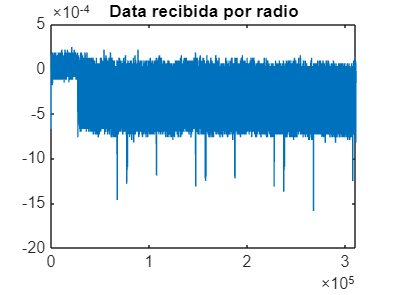



rec = read_float_binary('TEST_OOK_NOGAIN.bin')';

figure
plot(rec)
title("Data recibida por radio")


rxSignal = rec';


%% 4. LS Channel Estimation Using Pilot Symbols
% Extract the received pilot portion
rxPilot     = rxSignal(1:numPilotBits);
txPilot     = txSignal(1:numPilotBits);

Unrecognized function or variable 'txSignal'.


% LS Estimate of the channel (assuming single-tap)
% h_est = sum(rxPilot .* conj(txPilot)) / sum(|txPilot|^2) 
% but since OOK pilot symbols can be 0 or 1, we must only use the symbols that are "1"
% for a more robust estimate. Here, a simplified approach is used (all pilot samples).
h_est = (rxPilot' * txPilot) / (txPilot' * txPilot + eps);

% Alternatively, you could do: h_est = mean(rxPilot(txPilot==1))
% if your pilot bits contain sufficient '1's.

%% 5. Equalization and Demodulation
% Equalize the entire received signal (pilot+data)
eqSignal = rxSignal / (h_est + eps);

% Separate out the data portion only after equalization
eqDataSignal = eqSignal(numPilotBits+1:end);

% OOK Demodulation via threshold detection
% Decision rule: bit_hat = 1 if eqDataSignal > threshold; else 0
rxBits_hat = eqDataSignal > threshold;

%% 6. BER Calculation
% Compare with original transmitted data bits
numErrors  = sum(rxBits_hat ~= dataBits);
BER        = numErrors / numDataBits;

%% Results
fprintf('SNR = %2.1f dB\n', SNRdB);
fprintf('Estimated channel (LS) = %s\n', num2str(h_est));
fprintf('True channel          = %s\n', num2str(h));
fprintf('BER                   = %.5f\n', BER);

% Optionally, you can run this for a range of SNR values and plot the BER.



function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end

